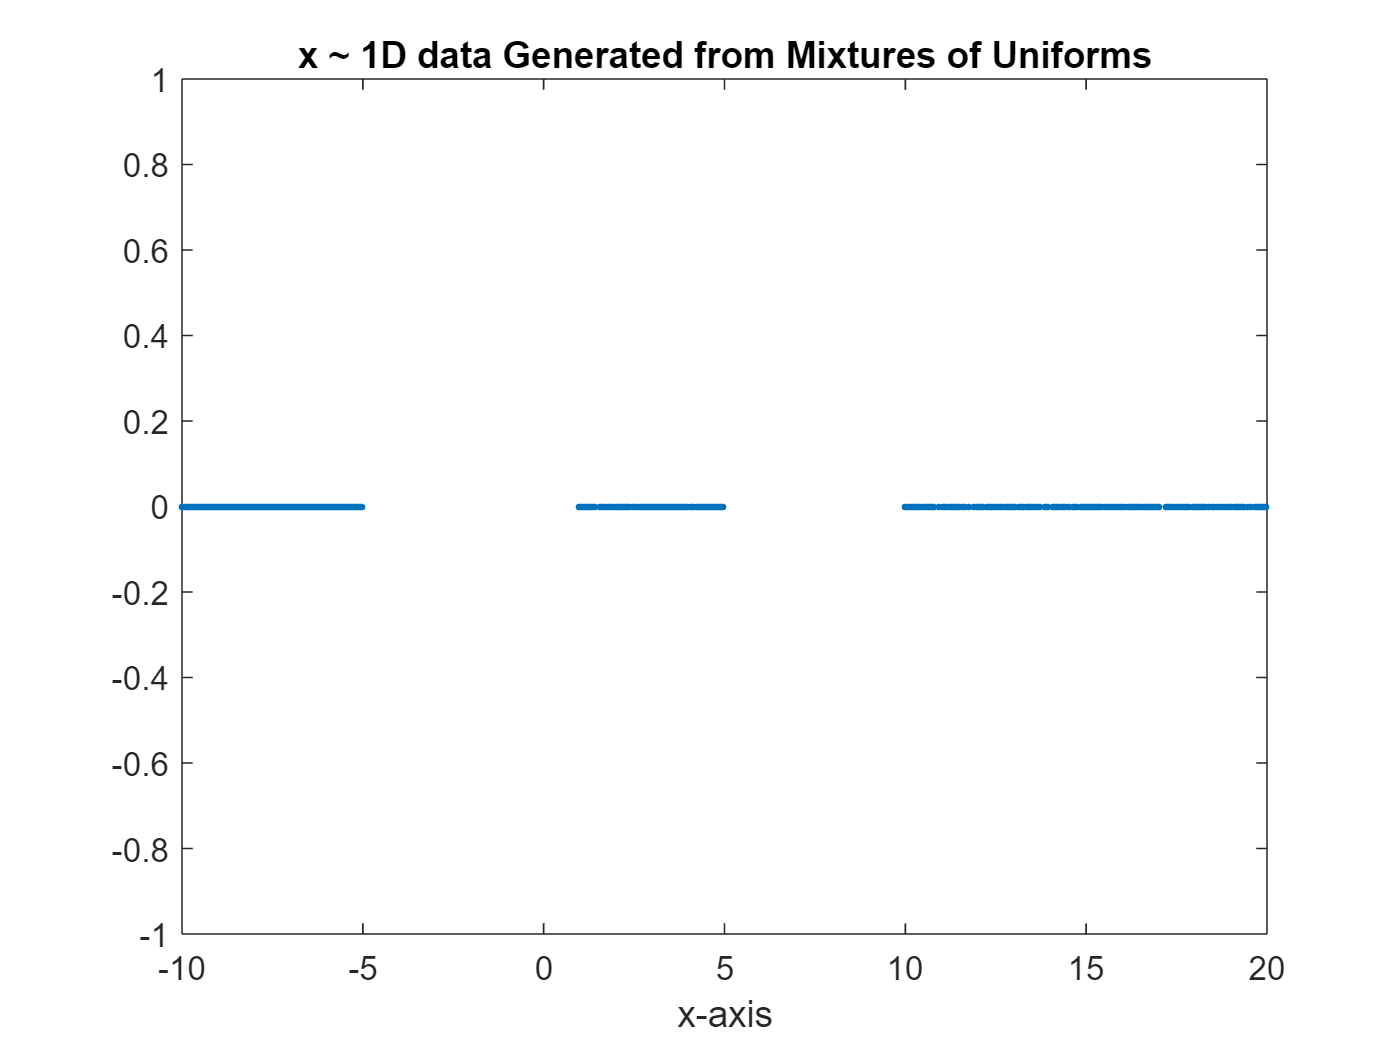

clc, clear all, close all,

N = 1000; % Specify the number of samples

%% 1D case
% Store parameters in a structure
ummParameters.priors=[0.2 0.5 0.3];%the likelihood of each distribution to be selected
ummParameters.a=[1 -10 10  ];%uniform distributions lower endpoints
ummParameters.b=[5 -5 20 ] ; %uniform distributions higher endpoints
% Generate 1D vector from 3 mixtures of Uniforms
V_uniform_1D = generateDataFromUMM(N,ummParameters,1); 

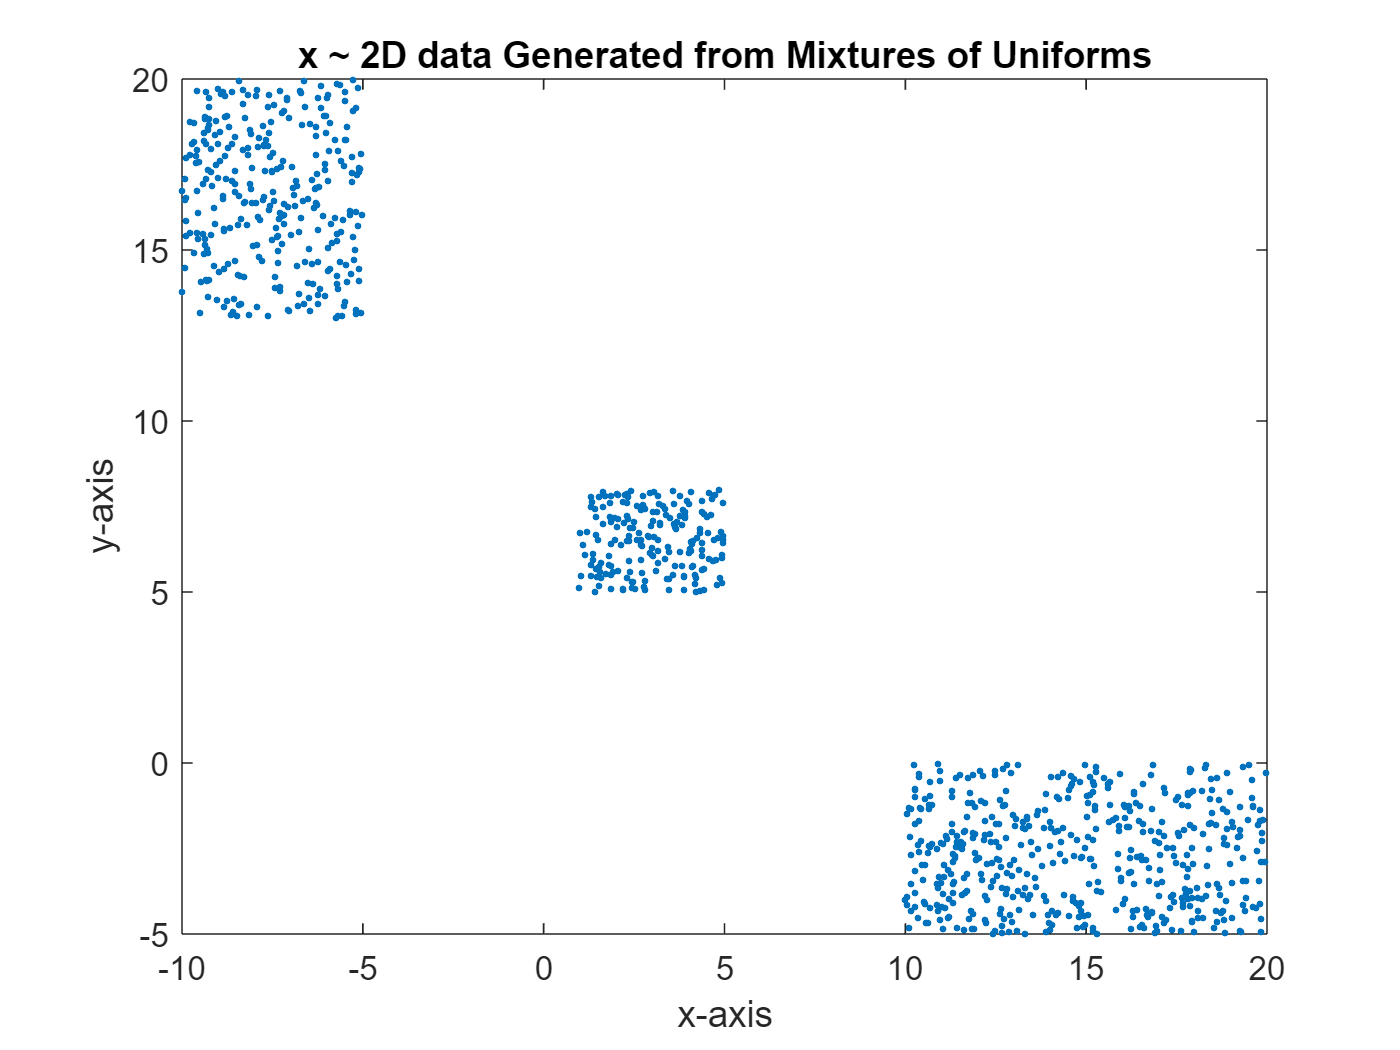


%% 2D case
clear ummParameters 
ummParameters.priors=[0.2 0.3 0.5];%the likelihood of each distribution to be selected
ummParameters.a=[1 -10 10 ; 5 13 -5 ];%uniform distributions lower endpoints for x and y axis
ummParameters.b=[5 -5 20;  8 20 0] ; %uniform distributions higher endpoints for x and y axis
% Generate 2D matrix from 3 mixtures of Uniforms
V_uniform_2D = generateDataFromUMM(N,ummParameters,1); 

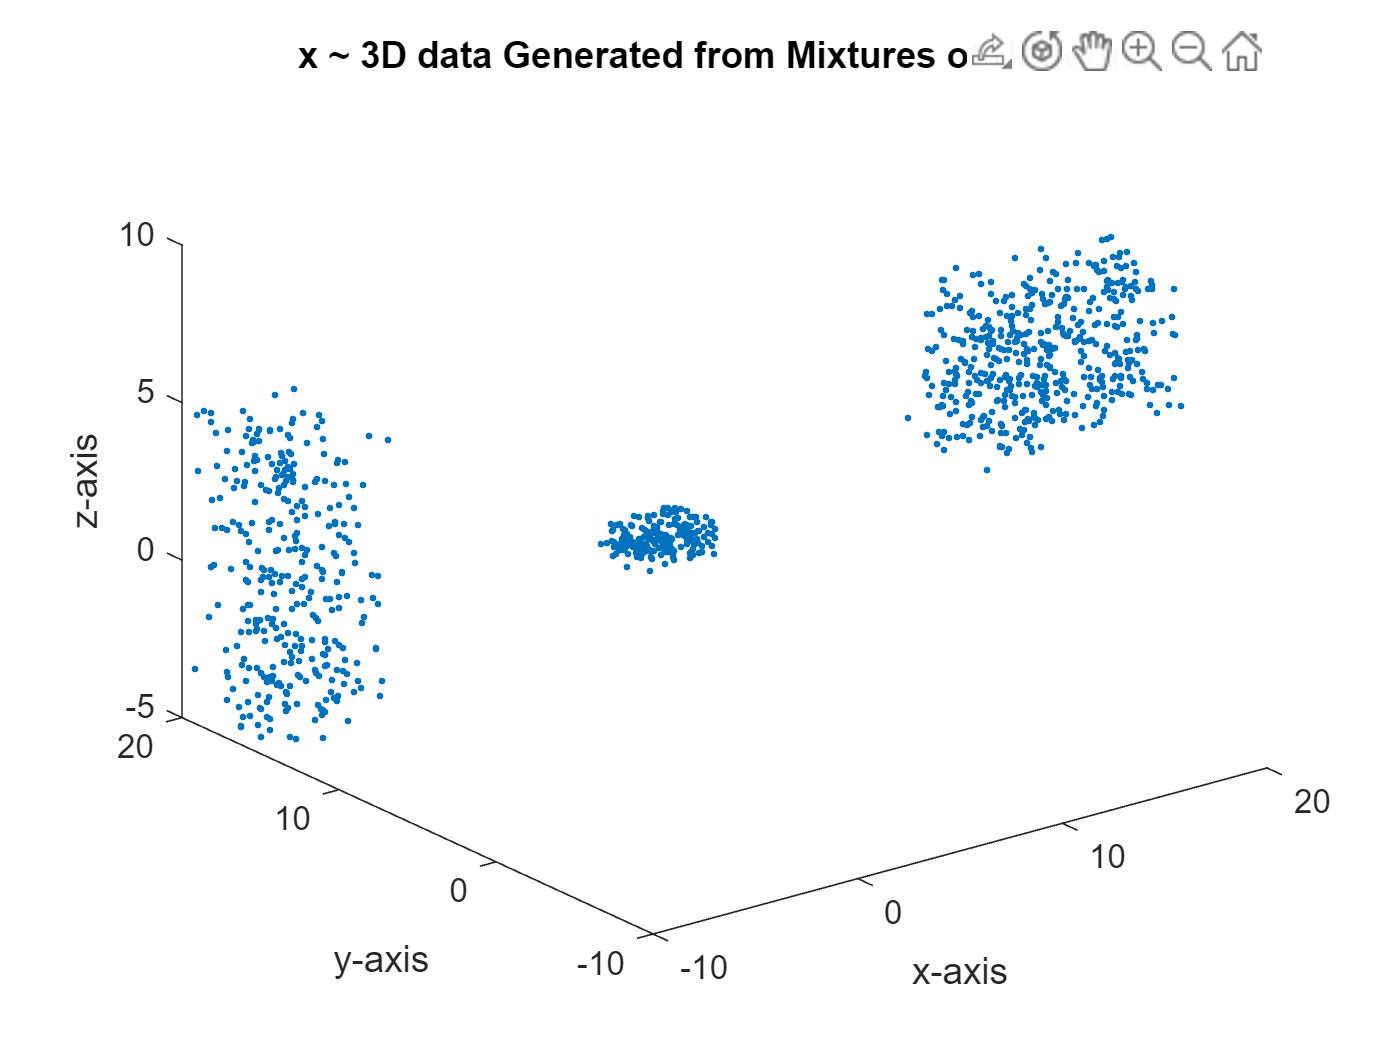


%% 3D case
clear ummParameters 
ummParameters.priors = [0.2 0.3 0.5];%the likelihood of each distribution to be selected
ummParameters.a = [1 -10 10 ; 5 13 -5; 1 -5  5];%uniform distributions lower endpoints for x, y and z axis
ummParameters.b = [5 -5 20;  8 20 0;2 5  10] ; %uniform distributions higher endpoints for x,y and z axis
% Generate 3D matrix from 3 mixtures of Uniforms
V_uniform_3D = generateDataFromUMM(N,ummParameters,1); 